clc; clear; 
Ea = 13.4E10; %elastic modulus ceramic
Em = 200E9; %[MPa]; %elastic modulus steel

rho_s = 7.7E3; %kg/m^3
rho_a = 7.7E3; %kg/m^3
U0 = 3.3; %micrometers
ha0 = 2E-3; %m

Fout = 1100; %Newton

P = 5/6;

A_a = (5E-3)^2;
A_c = (6.37E-3)^2;
A_T = (3.235E-3)^2;

h = 54.7E-3;
La = 18E-3;

Alpha = atan((h/2)/(La/2));
L_T = (La/(2*cos(Alpha)));
Alphadeg = rad2deg(Alpha);
%transmission ratio's
ia = La/h; 
iT = sin(Alpha);
CT = Em * A_T / L_T;
Cc = Em * A_c / h;
Ca = Ea * A_a / La;
Ctot = Cc + 0.5*CT*iT^2 + Ca*ia^2;
Csys = ((Cc)^-1 + (2*CT/iT)^-1)^-1;

%stiffnesses
F0 = Fout*ia;
       
%output stroke
umax = (La-ha0)/(ha0)*U0;
xp = (umax+F0/Ca)/(1+(Csys/Ca));
S_out = xp*ia;

%%massa
massa = rho_a*A_a*La;
massc = rho_s*A_c*h;
masst = 4*rho_s*A_T*(L_T);
masstotal = massa+massc+masst;
        
sc = Ctot/masstotal;

%Stiffness wire flexure
hf = [0.1:0.01:20]*1E-3;

for i = 1:length(hf)
%Clateral = E*d^4/hf^3
Clateral = Ctot/20;
df(i)= ((Clateral*0.6*hf(i)^3)/Em)^(1/4);
rf(i) = df(i)/2;
If(i) = (pi*rf(i)^4)/2;

Caxialreinfroced(i) = 3*(Em*(pi/4)*df(i)^2/hf(i));
Caxial(i) = Em*(pi/4)*df(i)^2/hf(i);

%sigmabmax = (3*Em*dflexure*z/hf^2)*(7/6);
sigmamax = 720E6;

zfr(i) = ((sigmamax)*hf(i)^2)/(3*Em*df(i));
zf(i) = (sigmamax*hf(i)^2)/(3*Em*df(i));

Fbucklereinforced(i) = (36*pi^2*Em*If(i))/hf(i)^2;
Fbuckle(i) = (4*pi^2*Em*If(i))/hf(i)^2;

cratiofr(i) = Caxialreinfroced(i)/Clateral;
cratiof(i) = Caxial(i)/Clateral;

vf(i) = pi*rf(i)^2*hf(i);
mf(i) = 2*vf(i)*rho_s;
end

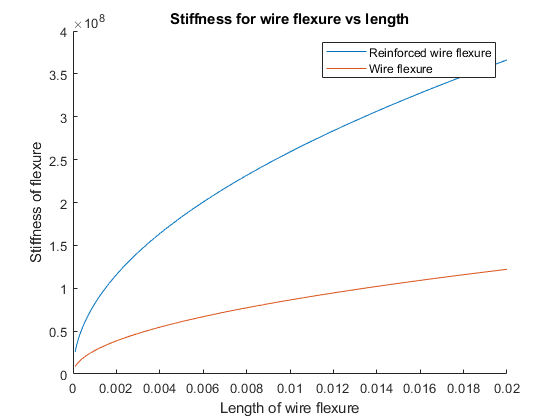

deltal = h/2+S_out;

figure()
hold on
plot(hf,Caxialreinfroced)
plot(hf,Caxial)
xlabel('Length of wire flexure')
ylabel('Stiffness of flexure')
title('Stiffness for wire flexure vs length')
legend('Reinforced wire flexure', 'Wire flexure')
saveas(gcf,'stiffnesses.png')